## **Finite Element Method**

clc; 
clear;
syms x f(x) u_e(x)

a=1

a = 1

b = 0

b = 0

c =1

c = 1

f(x) = 4*x^2 - 2*x -4;



%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

Value1 = 0;
Value2 = 1;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
ic2 = d_ue(1) == Value2;
%ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;
%----------------------------------------------------------------------------------


 P=2 % Only works till P = 6  % guass points restriction 

P = 2

% P Order of Interpolation Function foe element
ndofel=P+1;

% No of elements
e = 3;

% domain of X
x0 = 0;
xL = 1;

L = xL  % Length

L = 1


[K_global_D_bc,Fv,S,X] = FEM_Processor(P,e,L,a,b,c,f);



% At x0 
Q0 = 0; % f force value
K0 = 0;
Del0 = 0;
u0 = Value1;

% At xL
P0 = Value2;
K1 = 0;
Del1 = 0;
%uL = Value2;

Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));

Gv(1) = -Q0;
Sv(1) = -K0*Del0;

Gv(end) = P0;
Sv(end) = K1*Del1;

K_global_D_bc(1,1) = K_global_D_bc(1,1)-K0;
K_global_D_bc(end,end) = K_global_D_bc(end,end)-K1;


RHS = Fv + Gv + Sv;


% Check if A is specified as a number
if exist('u0', 'var') && isnumeric(u0)
    K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
    RHS(1) = u0;  % RHS of equation
end

if exist('uL', 'var') && isnumeric(uL)
    K_global_D_bc(end,:)= [zeros(1, S-1), 1];  %un=-1
    RHS(end) = uL;  % RHS of equation
end  


%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc\RHS);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point      u   
    ___________    ______

            0           0
      0.16667      1.1766
      0.33333      2.2042
          0.5      3.0541
      0.66667      3.7092
      0.83333      4.1633
            1      4.4227



disp("-------------------------------------------------------------")

-------------------------------------------------------------


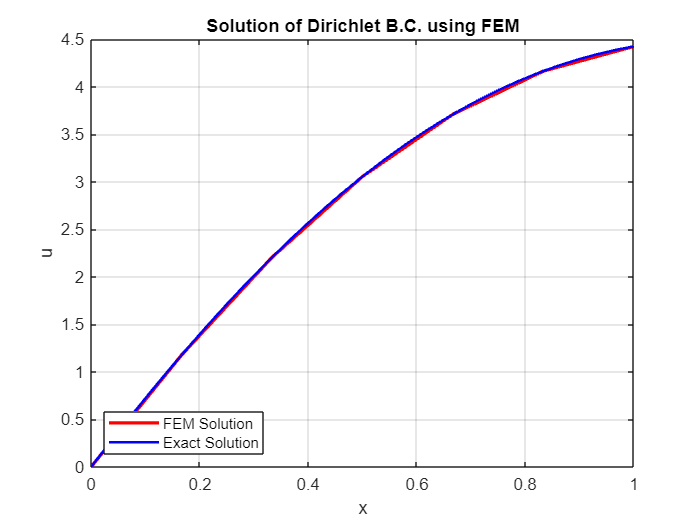

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [x0 xL], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;